# Reflectance Function Wrapper

By Andrew J. Buggee

clear variables;

## SET UP A FEW CONSTANTS AND VARIABLES

re = 4:4:20; % - microns - effective radius - value is in the file name
tau_c = [1,5:5:30]; % cloud optical thickness - value is in the file name
wavelengthBand = '0_65'; % this value is used to determine the right folder and file
waveLength_str = '0.65'; % this value is used for plotting purposes

## FILES TO RUN

folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/Hyperspectral-Cloud-Droplet-Retrieval-Research/',...
    'LibRadTran/libRadtran-2.0.4/Reflectance_Function_MODIS_',wavelengthBand,'mu_rev2/'];

% if this folder doesn't exist, create it!
if ~exist(folderName, 'dir')
   mkdir(folderName)
end

inputName = cell(length(re),length(tau_c));
outputName = cell(length(re),length(tau_c));

for ii = 1:length(re)
    for jj = 1:length(tau_c)

        inputName{ii,jj} = [wavelengthBand,'_micronBand_droplets_',num2str(re(ii)),'_microns_tau_',num2str(tau_c(jj)),'.INP'];
        outputName{ii,jj} = ['output_',wavelengthBand,'_micronBand_droplets_',num2str(re(ii)),'_microns_tau_',num2str(tau_c(jj))];


    end
end




## CALCULATE REFLECTANCE FUNCTION


% loop through the number of rows in the inputSettings cell array. Save
% everything, but only keep R in the workspace

% we will calculate R for every input file name
R = cell(size(inputName)); % each value here is integrated over the band provided
Rl = cell(size(inputName)); % each value here is the spectral reflectance over the entire band

for kk = 1:size(inputName,1)

    if kk == 1
        
    % start by running uvspec
    [inputSettings] = runUVSPEC(folderName,inputName(kk,:),outputName(kk,:));
    
    % save the input settings file. In this case each band will have the
    % same geometry so we only need to save a single settings file per band
    save([folderName,'settings.mat'],"inputSettings"); % save inputSettings to the same folder as the input and output file
    
    else
        runUVSPEC(folderName,inputName(kk,:),outputName(kk,:));
    end

    % read in the data structure and calculate reflectance function

    ds = cell(1,length(outputName(kk,:)));

    for jj = 1:length(outputName(kk,:))

        [ds{jj},~,~] = readUVSPEC(folderName,outputName{kk,jj},inputSettings(jj+1,:)); % headers don't change per iteration
        [R{kk,jj},Rl{kk,jj}] = reflectanceFunction(inputSettings(jj+1,:),ds{jj});

    end


end

% save reflectance function calculations

save([folderName,wavelengthBand,'mu_ReflectanceFunc.mat'],"R","Rl","tau_c","re"); % save inputSettings to the same folder as the input and output file





## PLOT REFLECTANCE FUNCTION

liveScriptPlotting
%     figure;
%
%     legendString2 = cell(1,length(changingVariable));
%
%     for jj = 1:length(outputName)
%
%         plot(ds{jj}.wavelength,Rl{jj})
%         hold on;
%         legendString2{jj} = num2str(changingVariable(jj));
%     end
%     xlabel('Wavelength (nm)')
%     ylabel('Reflectance Function (sr^{-1})')
%     grid on; grid minor
%     legend(legendString2,'textcolor','white')


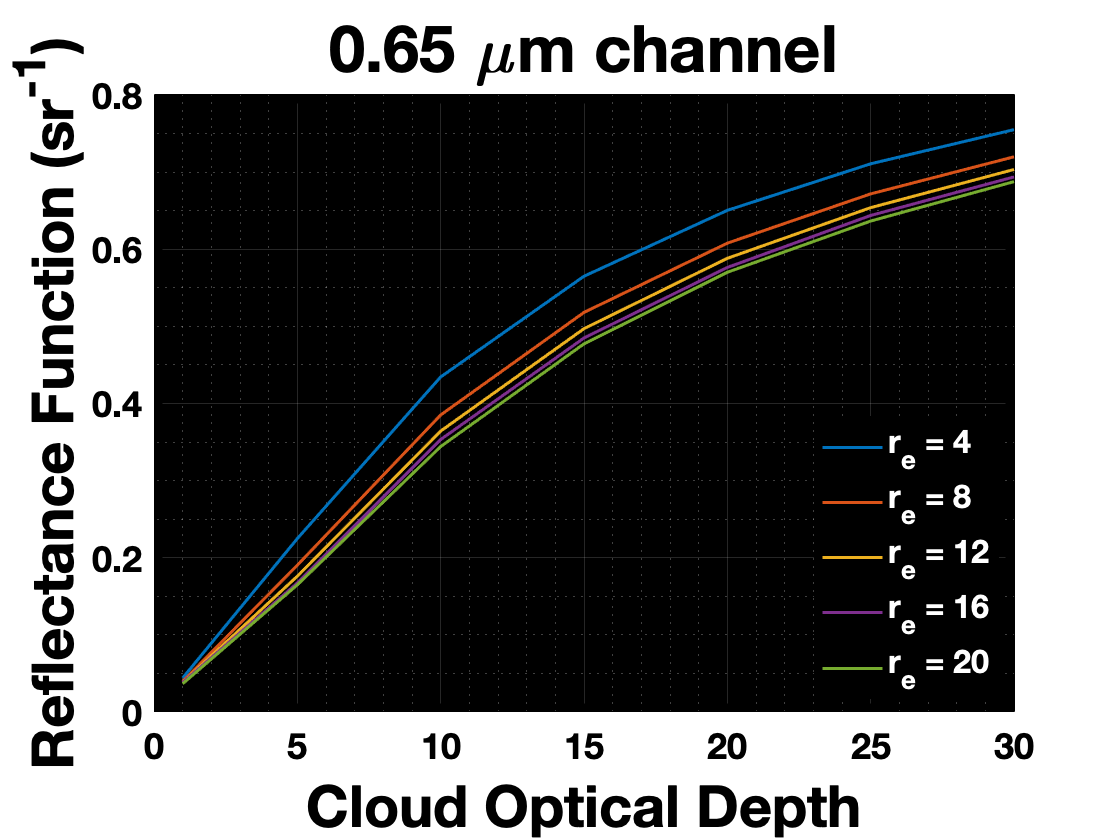

% Now lets plot the reflectance function versus optical depth

legendString = cell(1,size(R,1));
figure;
for ii = 1:size(R,1)
    plot(tau_c,[R{ii,:}],'linewidth',1.5)
    hold on;
    %     plot(tau_,[R{ii,:}],'b*')
    legendString{ii} = ['r_{e} = ',num2str(re(ii))];
end

xlabel('Cloud Optical Depth')
ylabel('Reflectance Function (sr^{-1})')
grid on; grid minor
legend(legendString,'textcolor','white','Location',"best")
title([waveLength_str,' \mum channel'])

## Plot Multiple Bands in One Large Window

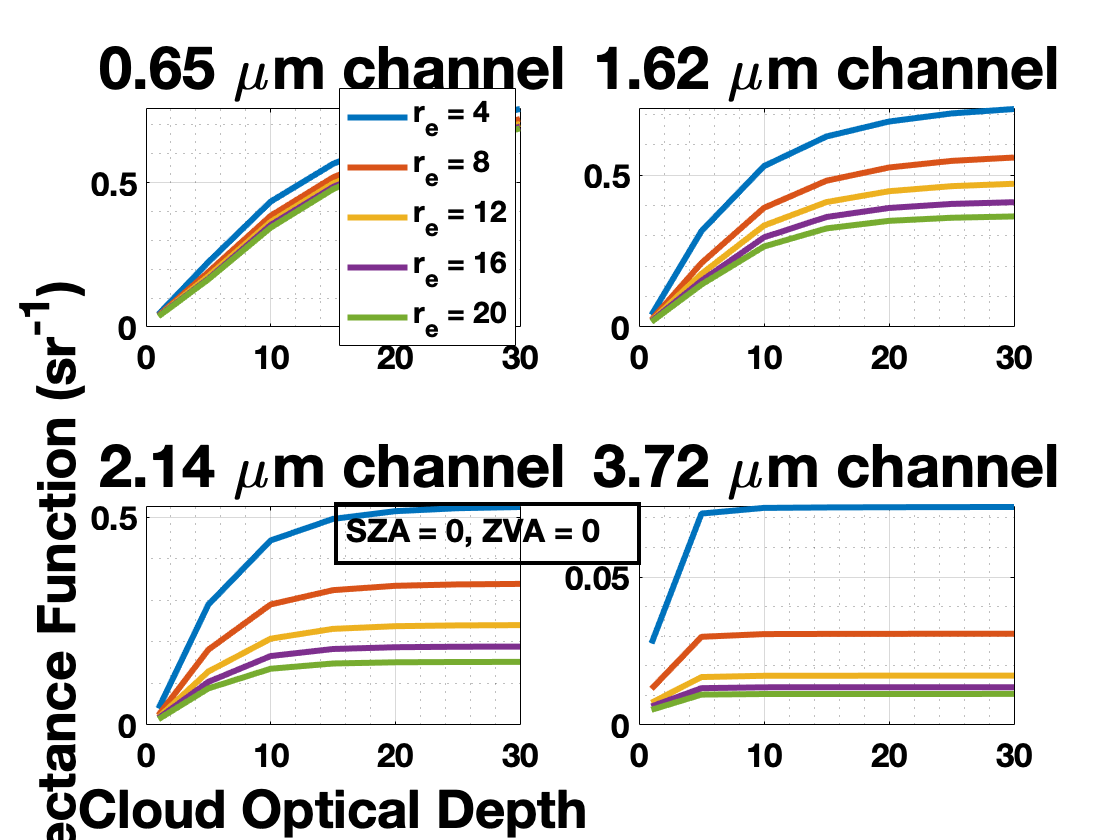

% provide folders and mat files for different R values at different
% wavelengths

blkFlag = false;

if blkFlag == true
    scriptPlotting_blk; % so I can pull this figure out and save it
    
else 
    scriptPlotting_wht; % assume white background in blk background is false
end


wl = {'0_65','1_62','2_14','3_72'};
wl_str = {'0.65','1.62','2.14','3.72'};

figure;

for ii = 1:length(wl)

    subplot(2,2,ii)

    folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/Hyperspectral-Cloud-Droplet-Retrieval-Research/',...
        'LibRadTran/libRadtran-2.0.4/Reflectance_Function_MODIS_',wl{ii},'mu_rev2/'];
    fileName = [wl{ii},'mu_ReflectanceFunc.mat'];

    A = load([folderName,fileName]);

    legendString = cell(1,size(A.R,1));
    for jj = 1:size(A.R,1)
        plot(A.tau_c,[A.R{jj,:}],'linewidth',3)
        hold on;
        %     plot(tau_,[R{ii,:}],'b*')
        legendString{jj} = ['r_{e} = ',num2str(A.re(jj))];
    end

    grid on; grid minor
    title([wl_str{ii},' \mum channel'])


    if ii == 1

        legend(legendString,'Location',"best")

    elseif ii == 3
        xlabel('Cloud Optical Depth')
        ylabel('Reflectance Function (sr^{-1})')
    end

end

annotation_str = 'SZA = 0, ZVA = 0';
if blkFlag == true
    a = annotation('textbox','EdgeColor','white','String',annotation_str,'FitBoxToText',"on",'Color','white',...
        'FontSize',16,'FontWeight',"bold",'LineWidth',2);
    set(gcf,'color','k')
else
     a = annotation('textbox','String',annotation_str,'FitBoxToText',"on",...
        'FontSize',16,'FontWeight',"bold",'LineWidth',2);
end